# Método de la rigidez en armaduras 2D

**Título completo:** Aplicación del método de la rigidez a estructuras de tipo armadura 2D (en el plano)

**Autor:** Isacc Alpala

## Contexto

Las armaduras en 2D son sistemas estructurales formados por barras rectas unidas en sus extremos mediante nodos. En ingeniería civil, las armaduras son cruciales para soportar cargas externas, convirtiendo las fuerzas aplicadas en esfuerzos internos (tensiones o compresiones) a través de las barras. Estas estructuras se utilizan comúnmente en puentes, techos, edificios y otras infraestructuras por su capacidad de distribuir cargas de manera eficiente y con un uso económico de materiales.

**Características de las armaduras**

- **Nodos**: Puntos donde las barras se conectan. Se asume que solo hay fuerzas en estos nodos (cargas nodales), y las fuerzas internas en las barras son puramente axiales (compresión o tensión).

- **Barras**: Los elementos estructurales que solo resisten esfuerzos axiales. No soportan momentos (giro) ni cortante.

- **Cargas**: Las cargas se aplican en los nodos y no directamente sobre las barras, lo que significa que no generan momentos en ellas.

- **Hipótesis de articulación**: Se asume que las barras están unidas mediante conexiones articuladas, lo que evita la transmisión de momentos y genera un análisis más simple.

**Importancia de las armaduras**

- **Optimización de materiales**: Las armaduras permiten distribuir las cargas de manera uniforme, utilizando eficientemente los materiales al resistir tensiones o compresiones sin necesidad de soportar momentos flexionantes.

- **Construcción ligera y eficiente**: Este tipo de estructuras son más livianas y requieren menos material, lo que las hace ideales para grandes luces (distancias entre apoyos) como en puentes o techos.

- **Estabilidad y rigidez**: Las armaduras proporcionan una estructura estable y rígida, evitando deformaciones importantes bajo cargas.

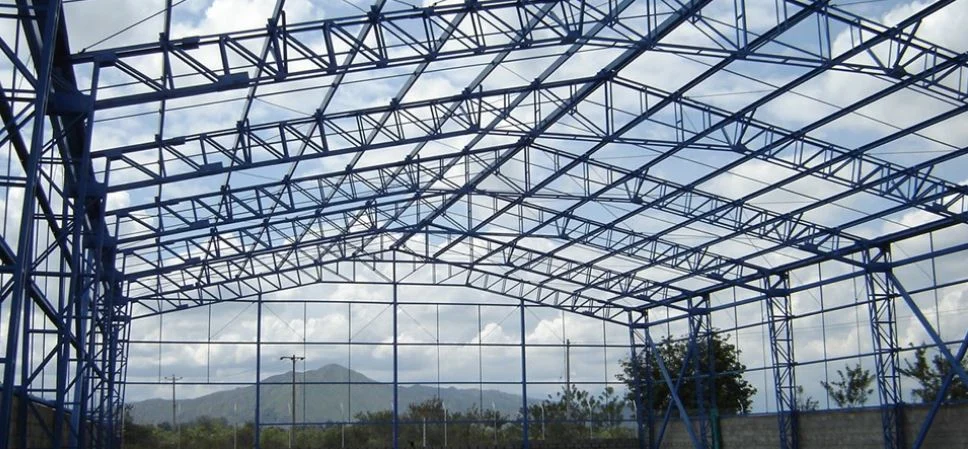

*Tomado de *[*Láminas y Aceros*](https://blog.laminasyaceros.com/blog/clases-de-cerchas-en-construcci%C3%B3n)*.*

### Parte teórica y de implementación

Se utiliza el **capítulo 14: Análisis de armaduras utilizando el método de la rigidez** del libro ***Análisis Estructural****, de R.C. Hibbeler, 8va edición, ****págs. 539-573***; para el desarrollo teórico y su implementación mediante programación (*la implementación no está incluida en el libro, pero sí algunas recomendaciones*).

### Parte práctica y de pruebas

Para realizar pruebas se puede utilizar los ejercicios adjuntos en el **libro antes mencionado**, **págs. 572-573**. Para verificar los resultados se puede revisar el apartado de **Repuestas a problemas seleccionados**, ubicado en la parte final del mismo libro, **págs. 678-679**.

## Requisitos

Se requiere conocimientos en:

- Álgebra lineal

- Resistencia de materiales

- Análisis estructural

## Entradas

La información que se necesita para **resolver la estructura** (***determinar desplazamientos, reacciones y fuerzas internas***) debe ser ingresada en el archivo Excel **aux_ejemplo_2.xlsx** (*aunque se puede modificar el nombre del archivo sin problema, ****no se debe modificar la organización de la información en él***).

Como recomendación, la información ingresada debe venir acompañada de:

- Un dibujo manual de la armadura junto la numeración de los nodos, numeración de los grados de libertad, numeración de los elementos y sentido de flujo. **La numeración de los grados de libertad debe ser secuencial en función del nodo**. Por ejemplo, el nodo 1 tendría los grados de libertad 1 y 2, el nodo 2 tendría los grados de libertad 3 y 4, etc.

- Un dibujo manual de la armadura junto con las reacciones (fuerzas desconocidas) y fuerzas aplicadas (fuerzas conocidas).

### Consideraciones sobre las unidades

En el archivo Excel de ingreso de datos **aux_ejemplo_2.xlsx** *se detalla lo que se debe ingresar y en qué unidades*. No obstante, **si es posible ingresar los datos en cualquier tipo de unidad** (o sistema de unidades) bajo las siguientes consideraciones:

- Todo lo que se relacione con longitud debe mantenerse con la misma unidad. Por ejemplo, utilizando el sistema inglés, si las coordenadas están en pies (unidad: $\text{ft}$), entonces el área debe estar en pies cuadrados (unidad: $\text{ft}^2$) y el módulo de elasticidad que relaciona $\frac{\text{fuerza}}{\text{área}}$ también se debe considerar con el área en pies cuadrados (unidad: $\text{ft}^2$). Por lo tanto, los resultados que relacionen la longitud también siguen estas consideraciones. Siguiendo el ejemplo, los desplazamientos estarían en pies (unidad: $\text{ft}$).

- Todo lo que se relacione con fuerza debe manterse con la misma unidad. Por ejemplo, utilizando el sistema inglés, si las fuerzas aplicadas a la estructura están en kilolibras (unidad: $\text{kip}$ o simplemente $\text{k}$), entonces el módulo de elasticidad que relaciona $\frac{\text{fuerza}}{\text{área}}$ se debe considerar con la fuerza en kilolibras (unidad: $\text{kip}$ o $\text{k}$). Por lo tanto, los resultados que relacionen la fuerza también siguen estas consideraciones. Siguiendo el ejemplo, las reacciones y fuerzas internas estarían en kilolibras (unidad: $\text{kip}$ o $\text{k}$).

### Esquemas gráficos del ejemplo de aplicación

*El siguiente ejemplo corresponde a los ejercicios ****14-1****, ****14-2**** y ****14-3**** del capítulo 14 del libro mencionado previamente (en la parte teórica), pág. 572. Los resultados se pueden corroborar en la pág. 678.*

Se resolverá la armadura detallada en los siguientes esquemas hechos a mano. El área y módulo de elasticidad de todas las barras es $A = 0.5 \text{ pulg}^2$ y $E = 29\times10^3 \text{ ksi}$. Recordar que $\text{ksi}$ es la abreviatura de kilolibras por pulgada cuadrada (**k**ilopounds per **s**quare **i**nch), es decir, $\text{ksi} = \text{k/pulg}^2$.

**Fig. 1.** Armadura original.

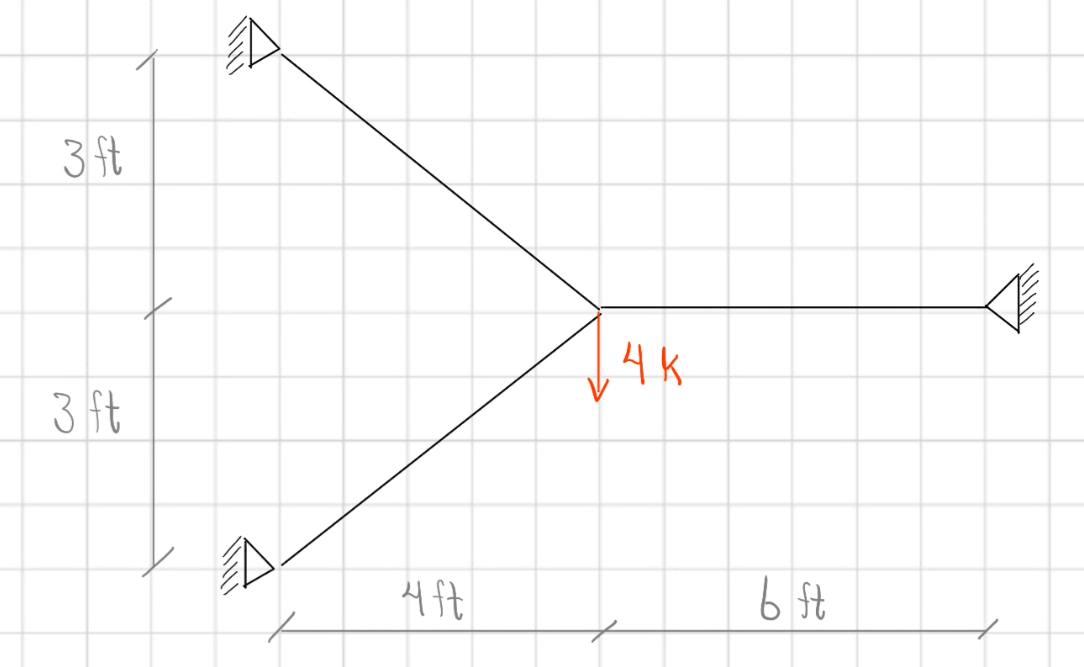

**Fig. 2.** Sentidos de flujo y enumeración de nodos y barras.

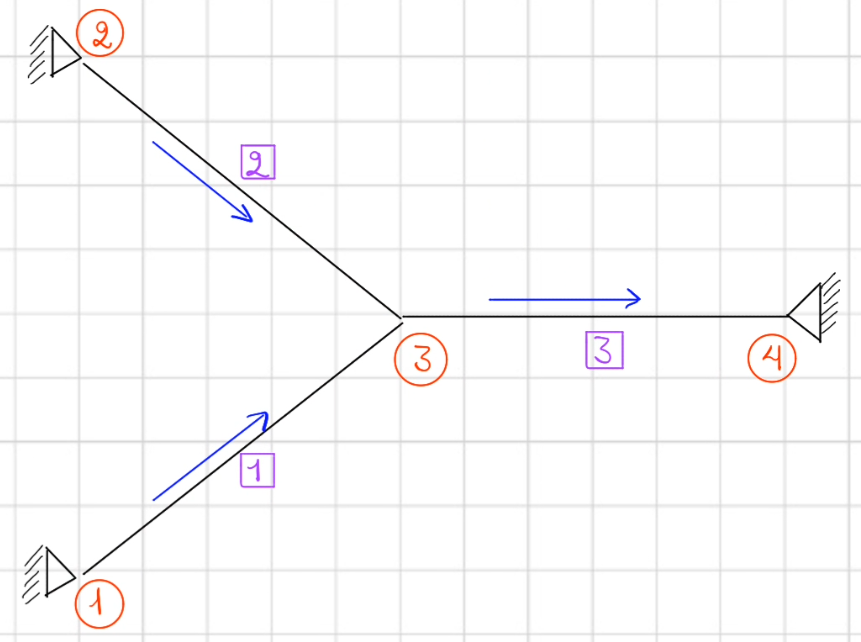

**Fig. 3.** Enumeración de grados de libertad.

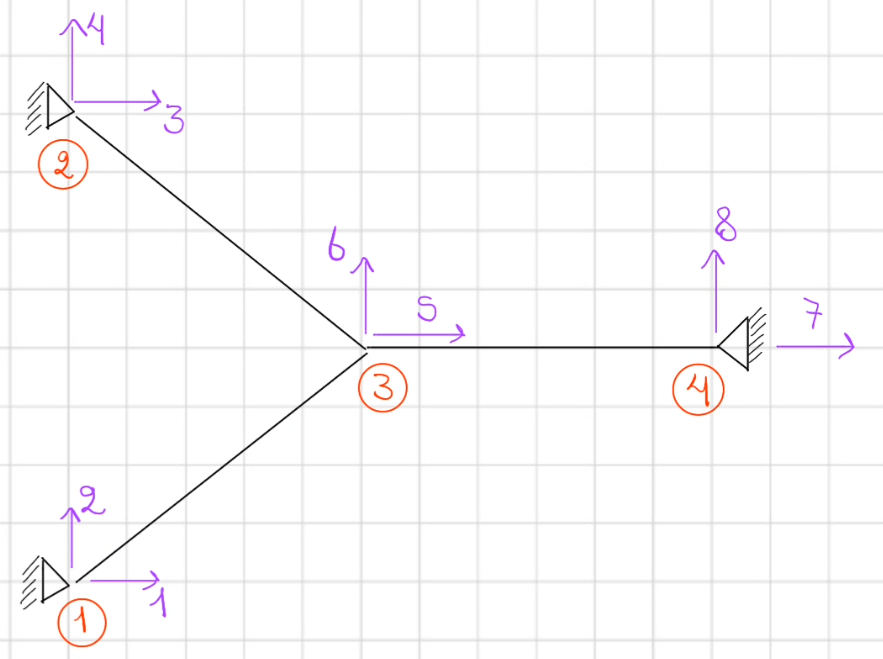

*Todas las imágenes son de autoría propia.*

### Preparación de ruta con funciones

Las siguientes líneas de código preparan el espacio de trabajo para la correcta ubicación de las funciones para aplicar el método de la rigidez y obtener los resultados.

***Se debe verificar que el espacio de trabajo sea el mostrado en pantalla***. Es decir, el espacio de trabajo actual sea la carpeta **armadura_2D**. Una vez verificado esto se puede ejecutar las siguientes líneas de código y continuar con el Ingreso de datos.

clear
cd ..\fncs\
userpath(pwd)
cd ..\armadura_2D\

### Ingreso de datos

Para la ejecución del código se deben ingresar las siguientes variables:

- El nombre del archivo Excel, y su extensión, que contiene toda la información de la estructura.

- El tipo de estructura: armadura, viga o pórtico.

- Si se debe convertir o no las unidades. Si se ingresa la información en el archivo Excel con las unidades detalladas en él, entonces sí se deben convertir las unidades. Caso contario, no.

*Para este ejemplo no es necesario realizar la conversión de unidades.*

nombre_archivo = "aux_ejemplo_2.xlsx";
tipo_estructura = "armadura";
convertir_unidades = false;

## Procedimiento

El procedimiento descrito a continuación es el utilizado para la solución completa, de inicio a fin, de la armadura aplicando el método de la rigidez. No obstante, los puntos resaltados en negrita son aquellos que son exclusivamente del método. El resto de puntos son pasos adicionales considerados en esta implementación.

- Importación de datos.

- **Visualización de la armadura.**

- Conversión de unidades.

- **Calcular y almacenar la matriz local de cada elemento.**

- **Calcular la matriz global de la estructura.**

- **Calcular las reacciones y los desplazamientos.**

- **Calcular las fuerzas internas.**

- Exportar resultados

### 1. Importación de datos

[nodos_tbl, elementos_tbl, desplazamientos_tbl, fuerzas_externas_tbl] = fnc_importar_datos(nombre_archivo);
disp(nodos_tbl)

    Nodo    Coordenada x    Coordenada y
    ____    ____________    ____________

     1            0               0     
     2            0              72     
     3           48              36     
     4          120              36     



disp(elementos_tbl)

    Elemento    Nodo inicio    Nodo fin    Área    Módulo de elasticidad
    ________    ___________    ________    ____    _____________________

       1             1            3        0.5             29000        
       2             2            3        0.5             29000        
       3             3            4        0.5             29000        



disp(desplazamientos_tbl)

    Nodo    Grado de libertad    Valor
    ____    _________________    _____

     1              1               0 
     1              2               0 
     2              3               0 
     2              4               0 
     3              5             NaN 
     3              6             NaN 
     4              7               0 
     4              8               0 



disp(fuerzas_externas_tbl)

    Nodo    Grado de libertad    Valor
    ____    _________________    _____

     1              1             NaN 
     1              2             NaN 
     2              3             NaN 
     2              4             NaN 
     3              5               0 
     3              6              -4 
     4              7             NaN 
     4              8             NaN 



### 2. Visualización de la armadura

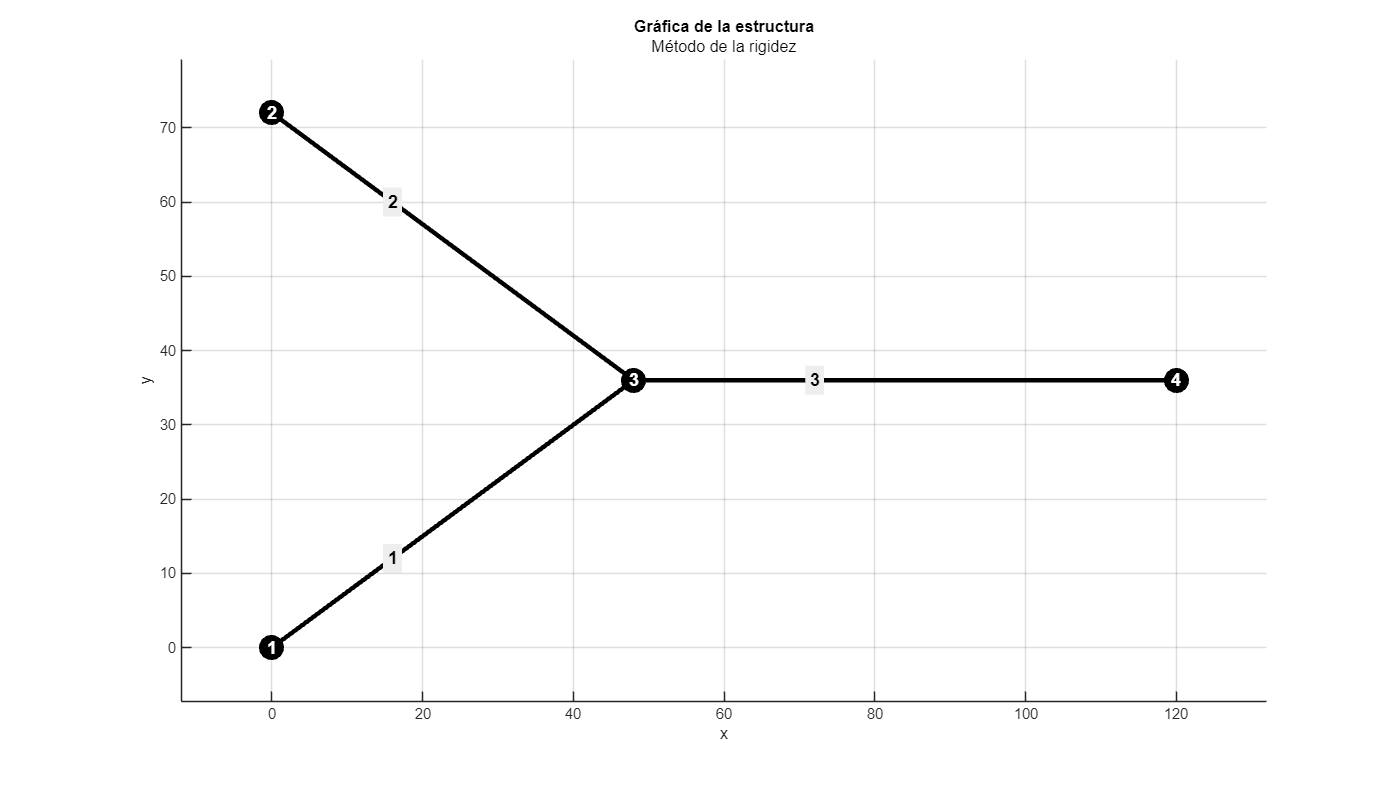

fnc_graficar_estructura(nodos_tbl, elementos_tbl, convertir_unidades)

### 3. Conversión de unidades

Dado que la información de las tablas debe ser coherente entre sí y sus unidades para los cálculos posteriores, se realizará las conversiones de unidades necesarias.

if convertir_unidades
    [nodos_tbl, fuerzas_externas_tbl] = fnc_convertir_unidades("cálculos", nodos_tbl, fuerzas_externas_tbl);
end

### 4. Calcular y almacenar la matriz local de cada elemento

k_local = fnc_matriz_local(nodos_tbl, elementos_tbl, tipo_estructura);

### 5. Calcular la matriz global de la estructura

k_global = fnc_matriz_global(k_local, tipo_estructura, elementos_tbl, nodos_tbl);

### 6. Calcular las reacciones y los desplazamientos

Para determinar las reacciones (fuerzas desconocidas) y desplazamientos (nodos no restringidos) se debe resolver dos sistemas de ecuaciones lineales detallados a continuación, los cuales surjen a partir de la ecuación de rigidez de la estructura.


$$\mathbf{Q} = \mathbf{K} \mathbf{D}$$


Y mediante particiones se tiene el sistema matricial:


$$\left[ \matrix{\mathbf{Q_k} \cr \mathbf{Q_u}} \right] = \left[ \matrix{\mathbf{K_{11}} & \mathbf{K_{12}} \cr \mathbf{K_{21}} & \mathbf{K_{22}}} \right] \left[ \matrix{\mathbf{D_u} \cr \mathbf{D_k}} \right]$$


El cual se puede desglosar en dos ecuaciones matriciales que sirven para determinar los desplazamientos y las reacciones de toda la estructura.

#### Sistemas de ecuaciones lineales para los desplazamientos

Para determinar los desplazamientos (en nodos no restringidos) se analiza de la siguiente manera:


$$\mathbf{Q_k} = \mathbf{K_{11}}\mathbf{D_u} + \mathbf{K_{12}}\mathbf{D_k} \\
\mathbf{K_{11}}\mathbf{D_u} = \mathbf{Q_k} - \mathbf{K_{12}}\mathbf{D_k}$$


Entonces se podría entender que


$$\mathbf{K_{11}}\mathbf{D_u} = \mathbf{Q_k} - \mathbf{K_{12}}\mathbf{D_k} \\
\mathbf{A}\mathbf{x} = \mathbf{b}$$


Donde $\mathbf{A} = \mathbf{K_{11}}$ y $\mathbf{b} = \mathbf{Q_k} - \mathbf{K_{12}} \mathbf{D_k}$, por lo tanto, aplicando operaciones matriciales se obtiene directamente los desplazamientos de la estructura $\mathbf{x} = \mathbf{D_u}$.

#### Sistema de ecuaciones lineales para las reacciones

Para determinar las reacciones (fuerzas desconocidas) se analiza de la siguiente manera:


$$\mathbf{Q_u} = \mathbf{K_{21}}\mathbf{D_u} + \mathbf{K_{22}}\mathbf{D_k} \\
\mathbf{C} = \mathbf{A} + \mathbf{B}$$


Donde $\mathbf{A} = \mathbf{K_{21}}\mathbf{D_u}$ y $\mathbf{B} = \mathbf{K_{22}}\mathbf{D_k}$, por lo tanto, aplicando operaciones matriciales se obtiene directamente las reacciones de la estructura $\mathbf{C} = \mathbf{Q_u}$.

***Los resultados de los desplazamientos y fuerzas externas (reacciones) desconocidas se adjutan a las tablas iniciales de desplazamiento y fuerza externa, complentando los datos que antes no se conocían.***

[desplazamientos_tbl, fuerzas_externas_tbl] = fnc_resolver_sistema(k_global, desplazamientos_tbl, fuerzas_externas_tbl);

### 7. Calcular las fuerzas internas

fuerzas_internas_tbl = fnc_fuerzas_internas(tipo_estructura, elementos_tbl, nodos_tbl, desplazamientos_tbl);

### 8. Exportar resultados

% Convertir unidades
if convertir_unidades
    [nodos_tbl, fuerzas_externas_tbl, fuerzas_internas_tbl] = fnc_convertir_unidades("resultados", nodos_tbl, fuerzas_externas_tbl, fuerzas_internas_tbl);
end

[nombre_archivo_resultados, nombre_imagen] = fnc_exportar_resultados(nombre_archivo, desplazamientos_tbl, fuerzas_externas_tbl, fuerzas_internas_tbl);

## Resultados

Los resultados son:

- Un nuevo archivo Excel, a partir del archivo Excel de ingreso de datos, con los resultados de aplicar el método de la rigidez.

- Una imagen de la estructura.

if isfile(nombre_archivo_resultados) && isfile(nombre_imagen)
    fprintf("El archivo %s se ha creado exitosamente.\n", nombre_archivo_resultados)
    fprintf("La imagen %s se ha creado exitosamente.\n", nombre_imagen)
else
    disp("No se han creado los archivos.")
end

El archivo aux_ejemplo_2 - Resultados 21-Oct-2024 21h16m40s.xlsx se ha creado exitosamente.


La imagen aux_ejemplo_2 - Resultados 21-Oct-2024 21h16m40s.png se ha creado exitosamente.


userpath("reset")

## Referencias

- Hibbeler, R. C. (2023). *ANALISIS ESTRUCTURAL* (8.a ed.). PRENTICE HALL/PEARSON.